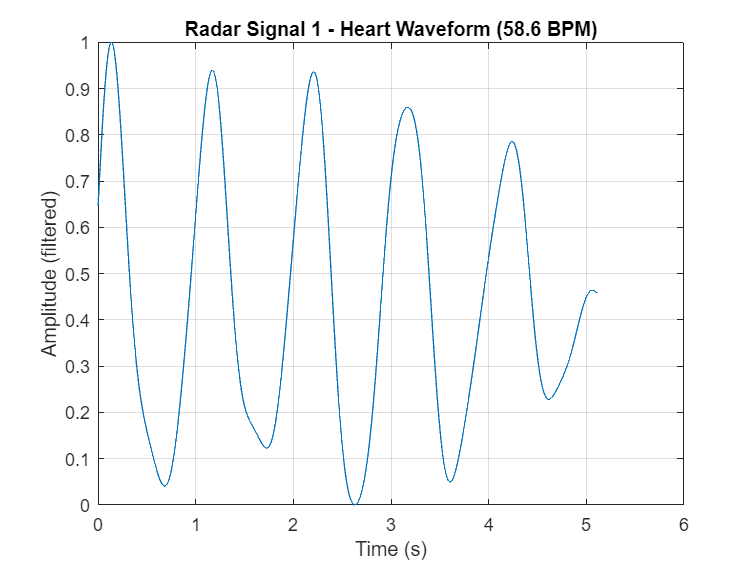

%%% Download dataset %%%
datasetZipFile = matlab.internal.examples.downloadSupportFile('SPT','data/SynchronizedRadarECGData.zip');
datasetFolder = fullfile(fileparts(datasetZipFile),'SynchronizedRadarECGData');
if ~exist(datasetFolder,'dir')     
    unzip(datasetZipFile,datasetFolder);
end

%%% Load all radar data (train + test combined) %%%
radarAllDs = signalDatastore([
    fullfile(datasetFolder,"trainVal","radar");
    fullfile(datasetFolder,"test","radar")
]);
ecgAllDs = signalDatastore([
    fullfile(datasetFolder,"trainVal","ecg");
    fullfile(datasetFolder,"test","ecg")
]);

% Read all radar signals
radarData = readall(radarAllDs);

% Normalize ECG signals
helperNormalize = @(x) { (x - median(x)) / max(abs(x - median(x))) };
ecgAllDs = transform(ecgAllDs, helperNormalize);

%%% Heart Rate FFT %%%
fs = 200; % sampling frequency
minHR = 48;  % min heart rate in BPM
maxHR = 150; % max heart rate in BPM
minFreq = minHR / 60; % ~0.8 Hz
maxFreq = maxHR / 60; % ~2.5 Hz
numSignalsToAnalyze = min(numel(radarData), 6);

% Bandpass filter for heart rate
d = designfilt('bandpassiir', 'FilterOrder', 6, ...
    'HalfPowerFrequency1', minFreq, 'HalfPowerFrequency2', maxFreq, ...
    'SampleRate', fs);

%%% Plot filtered heart rate %%%

i=1;
signal = radarData{i};
L = length(signal);
t = (0:L-1)/fs;

% Filter signal
filteredSignal = filtfilt(d, signal);
filteredSignal = (filteredSignal - min(filteredSignal)) / (max(filteredSignal) - min(filteredSignal));

% Estimate heart rate using FFT
Y = fft(filteredSignal);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = fs * (0:(L/2))/L;

idxBand = find(f >= minFreq & f <= maxFreq);
[~, maxIdx] = max(P1(idxBand));
domFreq = f(idxBand(maxIdx));
bpm = domFreq * 60;

% Graph
plot(t, filteredSignal)
title(sprintf("Radar Signal %d - Heart Waveform (%.1f BPM)", i, bpm))
xlabel("Time (s)")
ylabel("Amplitude (filtered)")
grid on